# Beamforming Example

clc
close all
clear

## Generate narrowband signal

fs = 100;
t = (0:1/fs:5).';
s = cos(2*pi*t); 

## Define array

fc = 9.5e9; % Operating fequency
antArray = phased.ULA("NumElements",16,"ElementSpacing",freq2wavelen(fc)/2); % Uniform Linear Array (ULA)
antArray.Element = phased.CosineAntennaElement;

## Simulate signals

azimuth = 45; 
sigCollector = phased.Collector("Sensor",antArray,"OperatingFrequency",fc);
rxsig = sigCollector(s,[azimuth; 0]); % Collect signal coming from azimuth angle

## Add receiver noise

rxrec = phased.Receiver("Gain",0,"NoiseMethod","Noise figure","NoiseFigure",125);
noisyRxsig = rxrec(rxsig);

## Display received signals

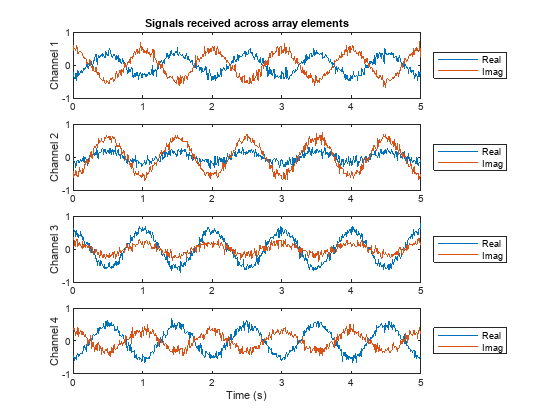

function will display first 4 channels


figure(1)
helperDisplayReceivedSignals(t,noisyRxsig)

## Delay-and-Sum Beamformer

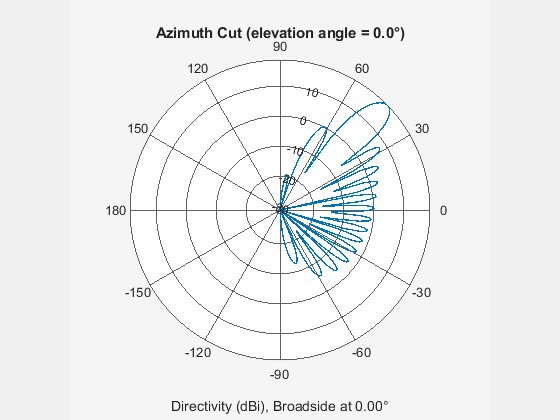

beamformer = phased.PhaseShiftBeamformer("SensorArray",antArray,"Direction",[azimuth; 0],...
    "OperatingFrequency",fc,"WeightsOutputPort",true);
[yBeam,wBeam] = beamformer(noisyRxsig);

% display radiation pattern for Phase-Shift Beamformed ULA
figure(2)
pattern(antArray,fc,-180:180,0,"Weights",wBeam) 

## Display Phase-Shift-beamformed received signals

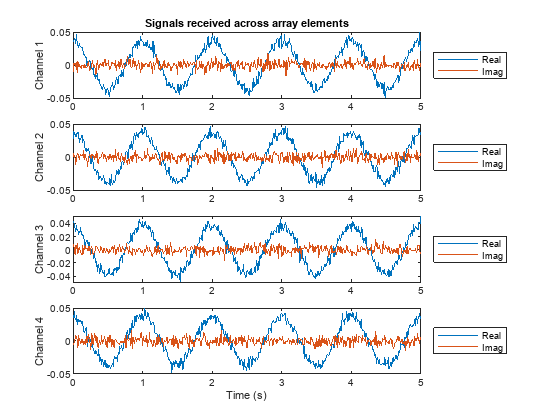

function will display first 4 channels


figure(3)
helperDisplayReceivedSignals(t,wBeam'.*noisyRxsig)

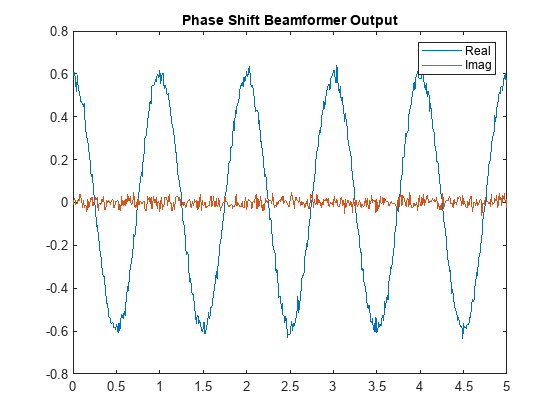


% display output signal of Phase Shift Beamformer
figure(4)
plot(t,real(yBeam),t,imag(yBeam))
legend("Real","Imag")
title("Phase Shift Beamformer Output")

## MVDR Beamformer

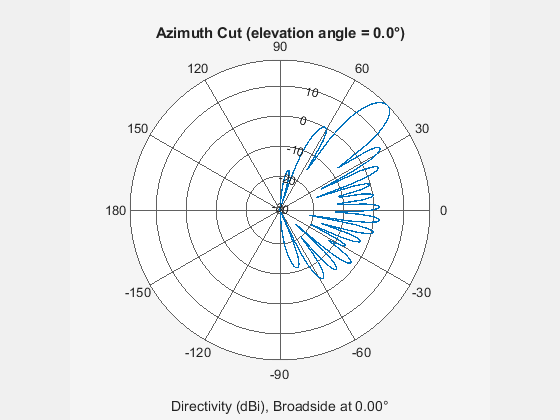

mvdrBeamformer = phased.MVDRBeamformer("SensorArray",antArray,"Direction",[azimuth; 0],...
    "OperatingFrequency",fc,"WeightsOutputPort",true,"DiagonalLoadingFactor",0.5);
[yMvdr,wMvdr] = mvdrBeamformer(noisyRxsig);

% display radiation pattern for MVDR Beamformed ULA
figure(5)
pattern(antArray,fc,-180:180,0,"Weights",wMvdr)

## Display MVDR-beamformed received signals

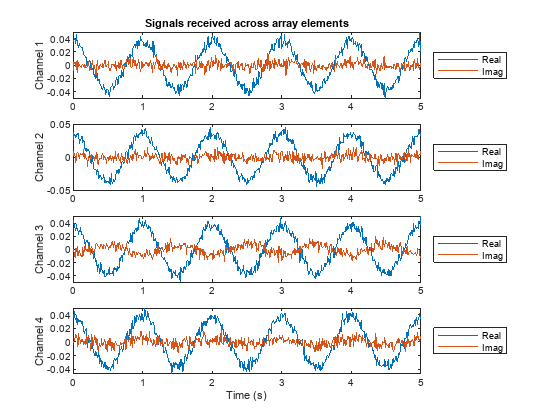

function will display first 4 channels


figure(6)
helperDisplayReceivedSignals(t,wMvdr'.*noisyRxsig)

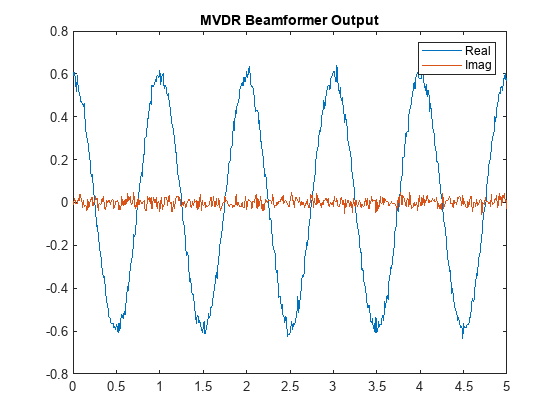


% display output signal of MVDR Beamformer
figure(7)
plot(t,real(yMvdr),t,imag(yMvdr))
legend("Real","Imag")
title("MVDR Beamformer Output")

function helperDisplayReceivedSignals(t,sig)
nElem = size(sig,2);
if nElem > 4
    disp("function will display first 4 channels")
    nElem = 4;
end
for m = 1:nElem
    subplot(nElem,1,m);
    plot(t,[real(sig(:,m)) imag(sig(:,m))]);
%    ylim([-1 1]);
    ylabel(sprintf("Channel %d",m));
    legend("Real","Imag","Location","EastOutside")
end
subplot(nElem,1,nElem);
xlabel("Time (s)");
subplot(nElem,1,1);
title("Signals received across array elements");
end